# Actuator Consideration Inner Loop

This document presents the plan to include the actuator dynamics in the inversion law for the inner loop of the Bebop controller. 

## Recap on Inner Loop Structure

The inner loop controls the attitude of the Bebop. The attitude can be expressed as


$$\left\lbrack \begin{array}{c}
\dot{p} \\
\dot{q} \\
\dot{r} 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{ccc}
I_{\textrm{xx}}  & 0 & 0\\
0 & I_{\textrm{yy}}  & 0\\
0 & 0 & I_{\textrm{zz}} 
\end{array}\right\rbrack }^{-1} \cdot \left(-\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack \times \left\lbrack \begin{array}{ccc}
I_{\textrm{xx}}  & 0 & 0\\
0 & I_{\textrm{yy}}  & 0\\
0 & 0 & I_{\textrm{zz}} 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack +\left\lbrack \begin{array}{cccc}
-b\cdot K_t  & b\cdot K_t  & b\cdot K_t  & -b\cdot K_t \\
l\cdot K_t  & l\cdot K_t  & -l\cdot K_t  & -l\cdot K_t \\
K_m  & {-K}_m  & K_m  & {-K}_m 
\end{array}\right\rbrack \cdot {\left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack }^2 \right)$$


Based on the free body diagram below

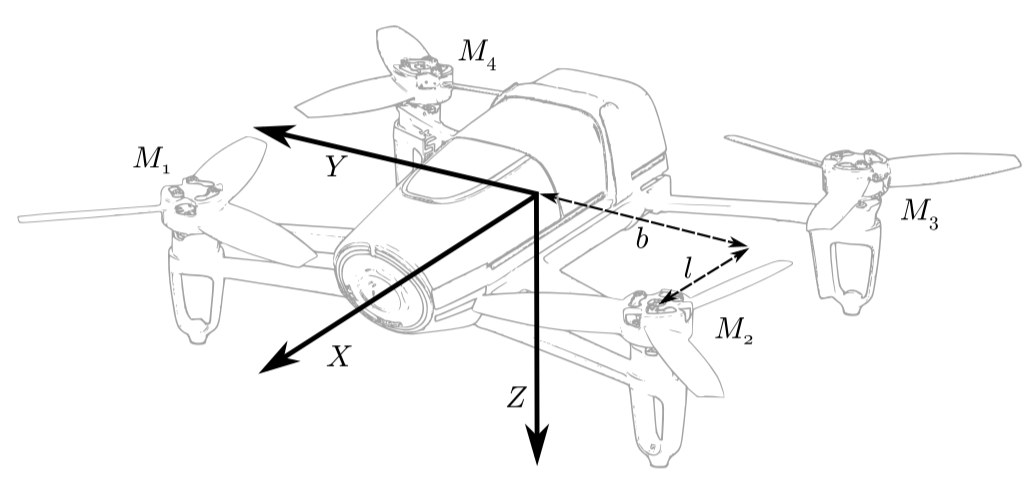

Where the first term is the inertia moment and the second term is the thrust induced moment. 

The inner loop law also takes into consideration the thrust increment, meaning that an expression for the thrust increment needs to be considered, as follows


$$T_b =\left\lbrack \begin{array}{cccc}
-K_t  & -K_t  & -K_t  & -K_t 
\end{array}\right\rbrack \cdot {\left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack }^2$$


The objective is to deliver the error of the attitude acceleration and thrust increment to the inversion law and get the rotations of the motors. To do this, the effectiveness matrix is required, and it can be obtained by differentiating each state increment wrt to each motor, leading to a 4x4 matrix that looks like this. 

B_inner(1,1) = -(2*K_t*Omega_1*b)/Ixx;
B_inner(1,2) = (2*K_t*Omega_2*b)/Ixx;
B_inner(1,3) = (2*K_t*Omega_3*b)/Ixx;
B_inner(1,4) = -(2*K_t*Omega_4*b)/Ixx;

B_inner(2,1) = (2*K_t*Omega_1*l)/Iyy;
B_inner(2,2) = (2*K_t*Omega_2*l)/Iyy;
B_inner(2,3) = -(2*K_t*Omega_3*l)/Iyy;
B_inner(2,4) = -(2*K_t*Omega_4*l)/Iyy;

B_inner(3,1) = (2*K_m*Omega_1)/Izz;
B_inner(3,2) = -(2*K_m*Omega_2)/Izz;
B_inner(3,3) = (2*K_m*Omega_3)/Izz;
B_inner(3,4) = -(2*K_m*Omega_4)/Izz;

B_inner(4,1) = -2*K_t*Omega_1;
B_inner(4,2) = -2*K_t*Omega_2;
B_inner(4,3) = -2*K_t*Omega_3;
B_inner(4,4) = -2*K_t*Omega_4;

The above can be used to estimated the RPMs of each motor. 

## Reference Model and Error Controller

The reference model and error controllers take the commands from the pilot and the outer loop to provide a feasible trajectory for the vehicle. The thrust increment does not need to pass through the RM and the EC, but the angles do, as we need to convert a angle command to an angular acceleration command. This is done as follows. Given the commands


$$\eta_{\textrm{cmd}} =\left\lbrack \begin{array}{ccc}
\phi_{\textrm{cmd}}  & \theta_{\textrm{cmd}}  & \psi_{\textrm{cmd}} 
\end{array}\right\rbrack$$


The angular acceleration vector reference can be obtained as follows


$$\ddot{\eta_{\textrm{ref}} } =K_{\dot{\eta} } \cdot \left(K_{\eta } \cdot \left(\eta_{\textrm{cmd}} -\eta_{\textrm{ref}} \right)-\eta_{\textrm{ref}} \right)$$


Where $\eta_{\textrm{ref}}$ is the attitude vector generated by the reference model, which can be expanded in terms of the command as


$$\ddot{\eta_{\textrm{ref}} } =\frac{K_{\dot{\eta} } \cdot K_{\eta } \cdot s^2 }{K_{\dot{\eta} } \cdot K_{\eta } +K_{\dot{\eta} } \cdot s+s^2 }\cdot \eta_{\textrm{cmd}}$$


with the lower orders as


$$\begin{array}{l}
\dot{\eta_{\textrm{ref}} } =\frac{K_{\dot{\eta} } \cdot K_{\eta } \cdot s}{K_{\dot{\eta} } \cdot K_{\eta } +K_{\dot{\eta} } \cdot s+s^2 }\cdot \eta_{\textrm{cmd}} \\
\eta_{\textrm{ref}} =\frac{K_{\dot{\eta} } \cdot K_{\eta } }{K_{\dot{\eta} } \cdot K_{\eta } +K_{\dot{\eta} } \cdot s+s^2 }\cdot \eta_{\textrm{cmd}} 
\end{array}$$


This is going to be fed as the ideal command for the inversion law. Of course, there is error to consider. An error controller is therefore employed, which is made as follows


$$\ddot{\eta_{\textrm{ec}} } =K_{\dot{\textrm{ec}} } \cdot \left(\dot{\eta_{\textrm{ref}} } -\dot{\eta} \right)+K_{\textrm{ec}} \cdot \left(\eta_{\textrm{ref}} -\eta \right)$$


Which leads to a desired angular acceleration that takes into consideration all the errors


$$\begin{array}{l}
\ddot{\eta_{\textrm{des}} } =\ddot{\eta_{\textrm{ref}} } +\ddot{\eta_{\textrm{ec}} } \\
\ddot{\eta_{\textrm{des}} } =\ddot{\eta_{\textrm{ref}} } +K_{\dot{\textrm{ec}} } \cdot \left(\dot{\eta_{\textrm{ref}} } -\dot{\eta} \right)+K_{\textrm{ec}} \cdot \left(\eta_{\textrm{ref}} -\eta \right)\\
\ddot{\eta_{\textrm{des}} } =\left\lbrack \left(\frac{K_{\dot{\eta} } \cdot K_{\eta } \cdot s^2 }{K_{\dot{\eta} } \cdot K_{\eta } +K_{\dot{\eta} } \cdot s+s^2 }\right)+K_{\dot{\textrm{ec}} } \cdot \left(\frac{K_{\dot{\eta} } \cdot K_{\eta } \cdot s}{K_{\dot{\eta} } \cdot K_{\eta } +K_{\dot{\eta} } \cdot s+s^2 }-\dot{\eta} \right)+K_{\textrm{ec}} \cdot \left(\frac{K_{\dot{\eta} } \cdot K_{\eta } }{K_{\dot{\eta} } \cdot K_{\eta } +K_{\dot{\eta} } \cdot s+s^2 }-\eta \right)\right\rbrack \cdot \eta_{\textrm{cmd}} 
\end{array}$$


$\ddot{\eta_{\textrm{des}} }$ is then compared to the actual $\eta$ to extract the required increment. 

## Actuator Consideration

The dynamics of the 4 motors can be expressed as a first order system


$$\dot{\Omega} =K_{\textrm{act}} \cdot \left(\Omega_{\textrm{cmd}} -\Omega \right)$$


Meaning that the state equations for attitude and thrust control can be differentiated further to include the dynamics of the actuators in the inversion law. 

If the state dynamics are neglected, we are looking at the following dynamics


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{p} \\
\dot{q} \\
\dot{r} 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{ccc}
I_{\textrm{xx}}  & 0 & 0\\
0 & I_{\textrm{yy}}  & 0\\
0 & 0 & I_{\textrm{zz}} 
\end{array}\right\rbrack }^{-1} \cdot \left\lbrack \begin{array}{cccc}
-b\cdot K_t  & b\cdot K_t  & -b\cdot K_t  & -b\cdot K_t \\
l\cdot K_t  & l\cdot K_t  & -l\cdot K_t  & -l\cdot K_t \\
K_m  & {-K}_m  & K_m  & {-K}_m 
\end{array}\right\rbrack \cdot {\left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack }^2 \\
T_b =\left\lbrack \begin{array}{cccc}
-K_t  & -K_t  & -K_t  & -K_t 
\end{array}\right\rbrack \cdot {\left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack }^2 
\end{array}$$


A differentiation of these states would lead to and expression that includes the actuator dynamics, because if


$$\ddot{x} =A\cdot \dot{x} +B\cdot \Omega$$


if differentiated, leads to

 
$$\ddot{x} =B\cdot \dot{\Omega} =B\cdot K_{\textrm{act}} \cdot \left(\Omega_{\textrm{cmd}} -\Omega \right)$$


Which is an inversion law with actuator dynamics inside. Now, this would then look like this


$$\left\lbrack \begin{array}{c}
\ddot{p} \\
\ddot{q} \\
\ddot{r} 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{ccc}
I_{\textrm{xx}}  & 0 & 0\\
0 & I_{\textrm{yy}}  & 0\\
0 & 0 & I_{\textrm{zz}} 
\end{array}\right\rbrack }^{-1} \cdot \left\lbrack \begin{array}{cccc}
-b\cdot K_t  & b\cdot K_t  & -b\cdot K_t  & -b\cdot K_t \\
l\cdot K_t  & l\cdot K_t  & -l\cdot K_t  & -l\cdot K_t \\
K_m  & {-K}_m  & K_m  & {-K}_m 
\end{array}\right\rbrack \cdot 2\cdot \left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
K_{\textrm{act}} \cdot \left(\Omega_{1,\textrm{cmd}} -\Omega_1 \right)\\
K_{\textrm{act}} \cdot \left(\Omega_{2,\textrm{cmd}} -\Omega_2 \right)\\
K_{\textrm{act}} \cdot \left(\Omega_{3,\textrm{cmd}} -\Omega_3 \right)\\
K_{\textrm{act}} \cdot \left(\Omega_{4,\textrm{cmd}} -\Omega_4 \right)
\end{array}\right\rbrack$$



$$\dot{T_b } =\left\lbrack \begin{array}{cccc}
-K_t  & -K_t  & -K_t  & -K_t 
\end{array}\right\rbrack \cdot 2\cdot \left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
K_{\textrm{act}} \cdot \left(\Omega_{1,\textrm{cmd}} -\Omega_1 \right)\\
K_{\textrm{act}} \cdot \left(\Omega_{2,\textrm{cmd}} -\Omega_2 \right)\\
K_{\textrm{act}} \cdot \left(\Omega_{3,\textrm{cmd}} -\Omega_3 \right)\\
K_{\textrm{act}} \cdot \left(\Omega_{4,\textrm{cmd}} -\Omega_4 \right)
\end{array}\right\rbrack$$


We see there the command increment $\Omega_{1,\textrm{cmd}} -\Omega_1$ typical of INDI and the required input to the inversion law, which is a second differentiation of the previous used dynamics. Now, is the B matrix the same as when linearized with the normal INDI method? Lets see


$$\left\lbrack \begin{array}{c}
\ddot{p} \\
\ddot{q} \\
\ddot{r} 
\end{array}\right\rbrack ={2\cdot \left\lbrack \begin{array}{ccc}
I_{\textrm{xx}}  & 0 & 0\\
0 & I_{\textrm{yy}}  & 0\\
0 & 0 & I_{\textrm{zz}} 
\end{array}\right\rbrack }^{-1} \cdot \left\lbrack \begin{array}{cccc}
-b\cdot K_t  & b\cdot K_t  & -b\cdot K_t  & -b\cdot K_t \\
l\cdot K_t  & l\cdot K_t  & -l\cdot K_t  & -l\cdot K_t \\
K_m  & {-K}_m  & K_m  & {-K}_m 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
\left(\Omega_{1,\textrm{cmd}} -\Omega_1 \right)\\
\left(\Omega_{2,\textrm{cmd}} -\Omega_2 \right)\\
\left(\Omega_{3,\textrm{cmd}} -\Omega_3 \right)\\
\left(\Omega_{4,\textrm{cmd}} -\Omega_4 \right)
\end{array}\right\rbrack \cdot K_{\textrm{act}}$$


If we solve the first 3 blocks we get

B_actuator(1,1) = -(2*K_t*Omega_1*b)/Ixx;
B_actuator(1,2) = (2*K_t*Omega_2*b)/Ixx;
B_actuator(1,3) = (2*K_t*Omega_3*b)/Ixx;
B_actuator(1,4) = -(2*K_t*Omega_4*b)/Ixx;

B_actuator(2,1) = (2*K_t*Omega_1*l)/Iyy;
B_actuator(2,2) = (2*K_t*Omega_2*l)/Iyy;
B_actuator(2,3) = -(2*K_t*Omega_3*l)/Iyy;
B_actuator(2,4) = -(2*K_t*Omega_4*l)/Iyy;

B_actuator(3,1) = (2*K_m*Omega_1)/Izz;
B_actuator(3,2) = -(2*K_m*Omega_2)/Izz;
B_actuator(3,3) = (2*K_m*Omega_3)/Izz;
B_actuator(3,4) = -(2*K_m*Omega_4)/Izz;

Which is indeed B, therefore


$$\left\lbrack \begin{array}{c}
\ddot{p} \\
\ddot{q} \\
\ddot{r} 
\end{array}\right\rbrack =B\cdot K_{\textrm{act}} \cdot \left\lbrack \begin{array}{c}
\left(\Omega_{1,\textrm{cmd}} -\Omega_1 \right)\\
\left(\Omega_{2,\textrm{cmd}} -\Omega_2 \right)\\
\left(\Omega_{3,\textrm{cmd}} -\Omega_3 \right)\\
\left(\Omega_{4,\textrm{cmd}} -\Omega_4 \right)
\end{array}\right\rbrack$$


The INDI inversion law therefore becomes


$$\left\lbrack \begin{array}{c}
\left(\Omega_{1,\textrm{cmd}} -\Omega_1 \right)\\
\left(\Omega_{2,\textrm{cmd}} -\Omega_2 \right)\\
\left(\Omega_{3,\textrm{cmd}} -\Omega_3 \right)\\
\left(\Omega_{4,\textrm{cmd}} -\Omega_4 \right)
\end{array}\right\rbrack =\frac{1}{B\cdot K_{\textrm{act}} }\cdot {\left\lbrack \begin{array}{c}
\ddot{p} \\
\ddot{q} \\
\ddot{r} 
\end{array}\right\rbrack }_{\textrm{des}}$$


### Obtaining the Feedforward

To get the feedforward we need to guess the dynamics of the rotational jerk. We have already the desired acceleration $\ddot{\eta_{\textrm{des}} } =\ddot{\eta_{\textrm{ref}} } +\ddot{\eta_{\textrm{ec}} }$, but we need the further differentiation of it, we need the jerk. Obtaining the jerk can be done by finding an ideal gain for the dynamics from acceleration to jerk, so


$$\eta_{\textrm{des}}^{\left(3\right)} =K_{\ddot{\eta} } \cdot \left(\ddot{\eta_{\textrm{cmd}} } -\ddot{\eta_{\textrm{ref}} } \right)$$


Ideally, this dynamics are as fast as the actuator, as the speed of the actuator affects directly the jerk, so it is safe to assume that $K_{\ddot{\eta} } \le K_{\textrm{act}}$. 

For the error controller, it is impossible to feed back the jerk, so that feedback is not there. However, the error controller will contain the tracking of the angular acceleration, leading to the expression


$$\eta_{\textrm{des}}^{\left(3\right)} =\eta_{\textrm{ref}}^{\left(3\right)} +\sum_{i=0} K_{{\textrm{ec}}_i } \cdot e_{\eta }^{\left(i\right)}$$


which would need an additional error coefficient for the error dynamics of the acceleration tracking. By looking at the expanded INDI control law proposed by Ewoud

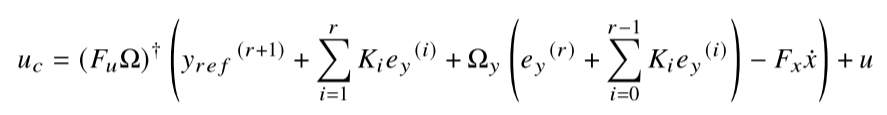

we can see that the error controller needs restructuring to obtain desired error dynamics. In brief, we need a new error controller so that


$$\begin{array}{l}
\eta_{\textrm{ec}}^{\left(3\right)} =\left({K_{\ddot{\textrm{ec}} } \cdot \left(\ddot{\eta_{\textrm{ref}} } -\ddot{\eta} \right)+K}_{\dot{\textrm{ec}} } \cdot \left(\dot{\eta_{\textrm{ref}} } -\dot{\eta} \right)+K_{\textrm{ec}} \cdot \left(\eta_{\textrm{ref}} -\eta \right)\right)+K_{\textrm{act}} \cdot \left(\left(\ddot{\eta_{\textrm{ref}} } -\ddot{\eta} \right)+K_{\dot{\textrm{ec}} } \cdot \left(\dot{\eta_{\textrm{ref}} } -\dot{\eta} \right)+K_{\textrm{ec}} \cdot \left(\eta_{\textrm{ref}} -\eta \right)\right)\\
\eta_{\textrm{ec}}^{\left(3\right)} ={\left(K_{\ddot{\textrm{ec}} } +K_{\textrm{act}} \right)\cdot \left(\ddot{\eta_{\textrm{ref}} } -\ddot{\eta} \right)+\;K}_{\dot{\textrm{ec}} } \cdot \left(1+K_{\textrm{act}} \right)\cdot \left(\dot{\eta_{\textrm{ref}} } -\dot{\eta} \right)+K_{\textrm{ec}} \cdot \left(1+K_{\textrm{act}} \right)\cdot \left(\eta_{\textrm{ref}} -\eta \right)
\end{array}$$


## Including the Thrust Increment

Similar care needs to be taken for the thrust increment. This one is simply delivered by the outer loop, is not estimated by a reference model or an error controller. What happens for 


$$T_{\textrm{cmd}} =\left\lbrack \begin{array}{cccc}
-K_t  & -K_t  & -K_t  & -K_t 
\end{array}\right\rbrack \cdot {\left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack }^2$$


is that it is delivered from the outer loop in the form of


$$T_{\textrm{cmd}} -T=\left\lbrack \begin{array}{cccc}
-{2\cdot K}_t \cdot \Omega_1  & -2\cdot K_t \cdot \Omega_2  & -2\cdot K_t \cdot \Omega_3  & -2\cdot K_t \cdot \Omega_4 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
\left(\Omega_{1,\textrm{cmd}} -\Omega_1 \right)\\
\left(\Omega_{2,\textrm{cmd}} -\Omega_2 \right)\\
\left(\Omega_{3,\textrm{cmd}} -\Omega_3 \right)\\
\left(\Omega_{4,\textrm{cmd}} -\Omega_4 \right)
\end{array}\right\rbrack$$


So that given the thrust increment we get the input increment. Now that we are compensating with the actuator, however, we need to deliver the derivative of the thrust as follows


$$\dot{T_{\textrm{cmd}} } =\left\lbrack \begin{array}{cccc}
-{2\cdot K}_t \cdot \Omega_1  & -2\cdot K_t \cdot \Omega_2  & -2\cdot K_t \cdot \Omega_3  & -2\cdot K_t \cdot \Omega_4 
\end{array}\right\rbrack \cdot K_{\textrm{act}} \cdot \left\lbrack \begin{array}{c}
\left(\Omega_{1,\textrm{cmd}} -\Omega_1 \right)\\
\left(\Omega_{2,\textrm{cmd}} -\Omega_2 \right)\\
\left(\Omega_{3,\textrm{cmd}} -\Omega_3 \right)\\
\left(\Omega_{4,\textrm{cmd}} -\Omega_4 \right)
\end{array}\right\rbrack$$


The question is then how do we move from $T_{\textrm{cmd}} -T$ to $\dot{T_{\textrm{cmd}} }$. If we model it as a reference model, it should simply look like this


$$\dot{T_{\textrm{cmd}} } =K_{\textrm{act}} \cdot \left(T_{\textrm{cmd}} -T\right)$$


Where we assume that the actuator dynamics are the thrust dynamics. 

## Assessment on Actuator Consideration

here the main discoveries associated with the actuator dynamics implementation are reported here. The cross frequency of the actuator of the Bebops are reduced from 50 to 20, so 60% slower. 

### Position Steady State Error

The position is not fed back to the controller, so a steady state error is introduced, in order to compensate for this, a integrator can be added to the error controller of the outer loop, this greatly improves the performance in position tracking, and the actuator improves disturbance rejection. 

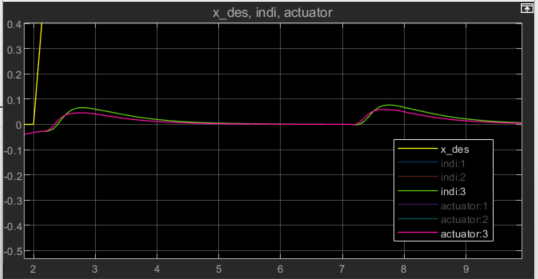

Given a desired velocity, the actuator consideration reduces the oscillations induced from its speed, allowing for a better following of the reference trajectory. 

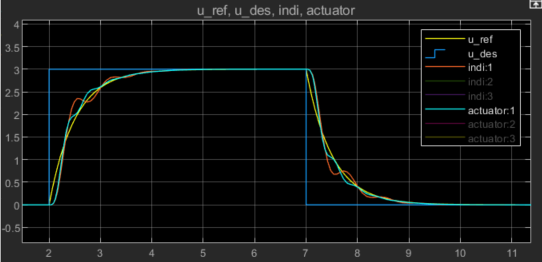

Disturbance rejection improvement can also be seen by looking at the external roll disturbance. 

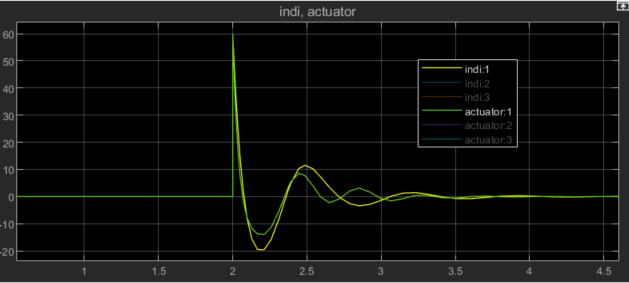

This has a good effect on higher levels, for example in position holding due to external disturbance (vertical position). 

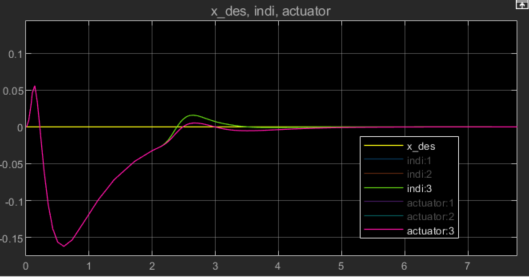

This is even more clear in the velocity field, where both y and z induced velocities are heaviliy damped. 

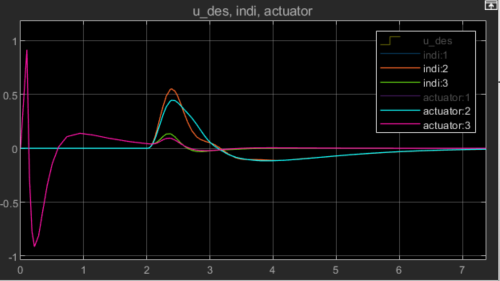

So there is clearly an improvement, and steady state errors are compensated better. 

In brief:

- better disturbance rejection

- better reference trajectory tracking

- steady state error compensation on error controller needed

There is an issue however when trying to push the drone to the limit, at the limit speed, for example at 13 m/s this happens

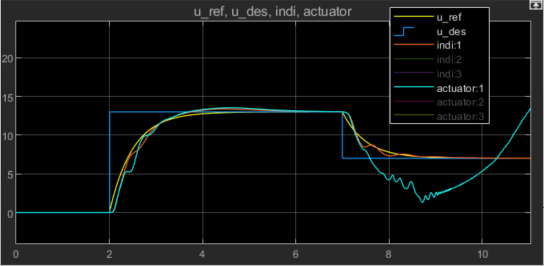

What is happening here and why? Why does the INDI holds the trajectory but the actuator one not? Do the gains for the inner loop need to be adjusted? Indeed, the actuator compensated seem a bit more aggressive in large accelerations? How do we deal with this? See here at slighly lower 11 m/s. This is interesting to research, defenitely.